# Sistemas Realimentados - 2026/1

## Nome: Sérgio Luiz Carneiro Junior

## Data limite para entrega: 20/6, meia-noite

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- Não é recebido por email

- Cabe a vocês garantir que o documento entregue é um** arquivo pdf legível**, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação. Espera-se os comentários solicitados.

- Caso não haja tempo de fazer todo o trabalho, entreguem no prazo o que estiver pronto.

## Trabalho 2 - Análise da resposta em frequência e projeto de controlador PID

**O código para mostrar os resultados é fornecido. Fiquem à vontade para melhorá-lo.**

**Obtenham os parâmetros solicitados no workspace do Matlab ou nos gráficos gerados, substituam no livescript, e removam os comentários para gerar os resultados, **

**que devem ser sempre comentados/explicados.**

**Removam os comentários apenas quando executarem a seção correspondente.**

I=29; % Seu valor de I
[p,g1,g2]=ini_t2(I)

p = -1.3500


g1 =
 
             1
  ------------------------
  s^3 + 23 s^2 + 62 s + 40
 
Continuous-time transfer function.


## Atividade 1: Critério de Nyquist

Seja o gráfico de Nyquist abaixo de $G(s)=\frac{K}{(s+a)(s+b)(s+c)}$, $a>0, b>0$, $c>0$.

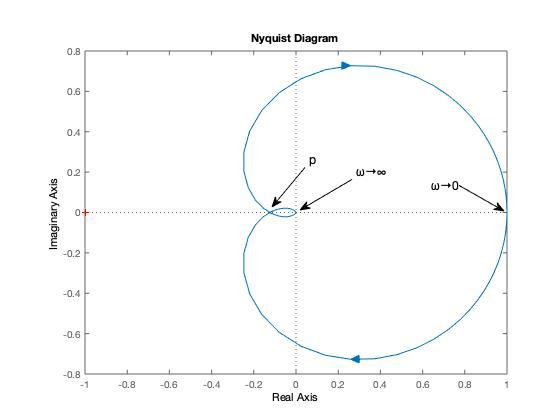

1.1 Considerando a equação do critério de Nyquist Z=N+P e o valor de p dado sobre o eixo real por onde cruza a curva, obtenha os valores de N e P explicando como obteve.

**A equação do critério de Nyquist **$$Z = N + P$$** surge do Princípio do Argumento de Cauchy. Nela, **$$Z$$** representa o número de zeros de **$$1 + G(s)H(s)$$** no Semiplano Direito (SPD) — correspondendo aos polos instáveis em malha fechada —, **$$P$$** é o número de polos em malha aberta no SPD, e **$$N$$** é o número de voltas no sentido horário em torno do ponto crítico **$$(-1, 0)$$**.**

**Analisando a função **$$G(s)$$** fornecida, seus polos de malha aberta estão localizados em **$$s = -a$$**, **$$s = -b$$** e **$$s = -c$$**. Como o enunciado garante que **$$a > 0$$**, **$$b > 0$$** e **$$c > 0$$**, todos esses polos estão no Semiplano Esquerdo (SPE), portanto, **$$P = 0$$**. Com isso, temos que **$$Z = N$$**.**

**Para determinar **$$N$$**, observa-se o ponto onde a curva cruza o eixo real negativo, dado por **$$p = - 1.35$$**. Como o ponto crítico analisado pelo critério é **$$(-1, 0)$$** e nota-se que **$$-1.35 < -1 < 0$$**, o ponto crítico encontra-se dentro da região delimitada pelos loops do diagrama. Ao considerar o contorno completo de Nyquist para a faixa de frequências de **$$-\infty$$** a **$$+\infty$$**, a curva mapeada envolve esse ponto crítico duas vezes no sentido horário. Logo, **$$N = 2$$**.**

**Substituindo os valores obtidos na equação do critério:**


$$$$Z = 2 + 0 \rightarrow Z = 2$$$$


**Como **$$Z = 2$$**, o sistema em malha fechada possui polos no Semiplano Direito, sendo, portanto, instável.**

1.2 Verifique se este sistema é estável em malha fechada e obtenha Z.

**Com base no que foi apresentado na questão 1.1, temos os valores de **$$P = 0$$** pois os polos em malha aberta estão no SPE. Além disso, como temos o ponto que cruza o eixo real negativo (**$$p = -1.35$$**) e o ponto crítico é analisado em **$$(-1, 0)$$** temos que **$$-1.35 < -1 < 0$$** e portanto o ponto crítico está dentro da região delimitada no gráfico. Considerando a faixa de frequências de **$$-\infty$$** a **$$+\infty$$**, temos que a curva mapeada envolve o ponto crítico duas vezes no sentido horário e portanto **$$N = 2$$**. Logo, como tempo **$$$ Z = N + P \rightarrow Z = 2 + 0 \rightarrow Z = 2$$$**, chegamos na conclusão que o sistema em malha fechada possui polos no SPD o que considera como instável.**

1.3 Obtenha a Margem de Ganho em dB e veja o que se pode afirmar sobre a Margem de Fase.

**A Margem de Ganho e a Margem de Fase podem ser determinadas pelo diagrama de Nyquist analisando a interseção com o eixo real negativo e a interseção com o círculo unitário. A Margem de Ganho indica o quanto pode multiplicar o ganho do sistema antes que ele se torne instável, ou seja, antes da curva englobar o ponto crítico -1 nesse caso. Como o ponto de interseção do eixo real negativo é p = -1.35, então a Margem de Ganho é dada por **


$$$$MG = \frac{1}{|p|} \rightarrow MG = \frac{1}{|-1.35|}\rightarrow MG = 0.7407$$$$



$$$$MG_{dB} = 20 \log_{10}(MG) \rightarrow MG_{dB} = 20 \log_{10}(0.7407)  \rightarrow MG_{dB} = 20 \cdot (-0.1303)= -2.607 \text{ dB}$$$$


**Portanto, a Margem de Ganho absoluta é 0.7407, o que equivale a -2.607 dB.**

**A Margem de Fase indica o quanto de atraso de fase pode adicionar ao sistema antes que a curva toque o ponto crítico -1. No gráfico, imagine um círculo de raio 1 centrado na origem (círculo unitário), então procura-se o ponto exato onde a curva de Nyquist intersecta esse círculo unitário.  Como p = -1.35, então haverá 5 pontos de interseção da curva de Nyquist com o círculo unitário considerando frequências positivas e frequências negativas. Com base nisso teremos 5 Margens de Fase, mas como a Margem de Ganho foi menor que zero isso significa que a Margem de Fase também será menor que zero então os possíveis pontos de interseção para essa Margem de Fase estão localizados no segundo quadrante. Logo, a que "define" o sistema seria a Margem de Fase que apresenta a menor margem em valor absoluto (aquela que está angularmente mais próxima do eixo real negativo). A imagem a seguir é um esboço para uma melhor visualização e é possível ver que a margem de fase é menor que -180°, logo a MF < 0.**

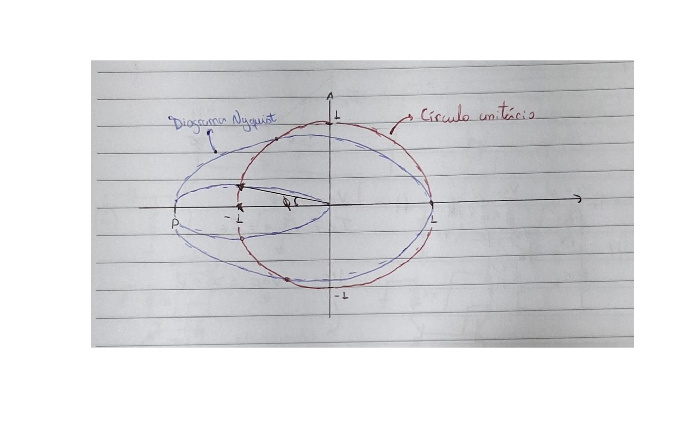

figure;
imshow('DiagramaNyquist_questao1.jpeg');

## Atividade 2: Critério de Nyquist usando o Gráfico de Bode

Seja o gráfico de Bode de G(s) e a equação do critério de Nyquist Z=N+P.

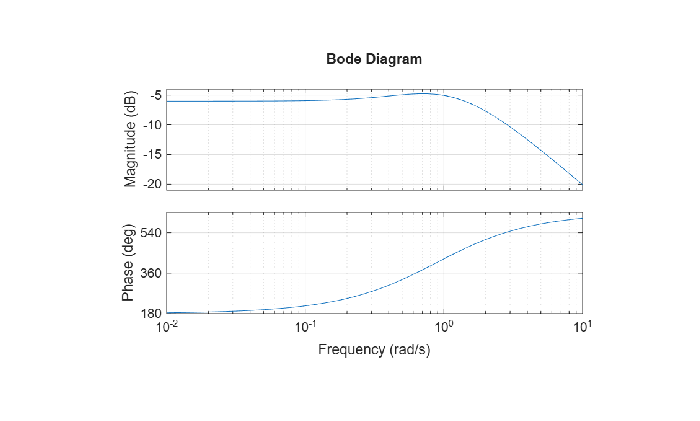

figure;
imshow('Item2.png');

2.1 Obtenha P a partir deste gráfico, explicando como obteve.

**Pelo diagrama de Bode, podemos notar que quando **$$\omega \to 0$$** o gráfico de magnitude não possui inclinação (0 dB/déc), mas o gráfico de fase começa em 180°. Esse comportamento é devido ao um ganho DC cujo valor é negativo e pode ser interpretado na fase como +180° ou -180°. Basicamente, é o ponto de partida definido pela FT de malha aberta.**

**Para determinar a quantidade de polos de malha aberta no SPD (**$$P$$**), precisamos analisar a dinâmica do sistema nas demais frequências. Ao longo do gráfico, a fase cresce continuamente de 180° até atingir uma assíntota final em 630°, resultando em um acréscimo total de +450°. Sabendo que cada polo no SPD e cada zero no SPE contribuem com +90° na fase, concluímos que a soma total desses elementos é igual a 5 (**$$P + z = 5$$**).**

**Simultaneamente, analisando o gráfico de magnitude para altas frequências (como na década de **$$\omega = 1$$** a **$$\omega = 10$$**), nota-se uma inclinação final de -20 dB/déc. Isso indica que a função de transferência possui exatamente 1 polo de malha aberta no SPD a mais do que o número de zeros no SPE, logo, **$$P - z = 1$$

**Resolvendo o sistema linear formado por essas duas equações:**


$$$$P + z = 5$$$$



$$$$P - z = 1$$$$


**Somando ambas, obtemos **$$2P = 6 \rightarrow P = 3$$**. Portanto, o número de polos no Semiplano Direito é P = 3.**

**Com P=3 e Z=2, podemos perceber que quem definiu o ponto de partida da fase em 180° foram justamente os polos no SPD.**

2.2 Desenhe o gráfico de Nyquist correspondente e obtenha N.

**O gráfico de Nyquist mostra o comportamento do sistema **$$G(s)$$** em malha aberta. Para saber se a curva pode conter o ponto crítico precisamos encontrar o valor de p (ponto de interseção com o eixo real negativo). Sabemos que o eixo real negativo terá ângulos múltiplos ímpares de 180° (540°, -180°,etc). Como no diagrama de Bode o gráfico começa em 180° sem tocá-lo e vai aumentando, o próximo ângulo seria 540° no qual o grafico passa por ele visto que o grafico vai até a assintóta em 630°. No ângulo de 540° olhamos a frequência e a magnitude nesse ponto que seria aproximadamente w = 2 rad/s e A(dB) = -10. Como o diagrama de Nyquist é traçado em escala linear precisamos converter a magnitude em dB, a conversão é:**


$$$$\text{Magnitude Linear} = 10^{\frac{\text{Magnitude em dB}}{20}}$$$$



$$\text{Magnitude Linear} = 10^{\frac{\text{-10}}{20}} \to \text{Magnitude Linear} = 0.316$$


**Logo, o ponto p está aproximadamente a uma distância de 0.316 da origem.**

**Portanto, como p está entre -1 e 0 (**$$-1 < -0.316 < 0$$) **não tem envolvimento em torno do ponto crítico então N = 0.**

**O esboço do gráfico de Nyquist está logo abaixo.**

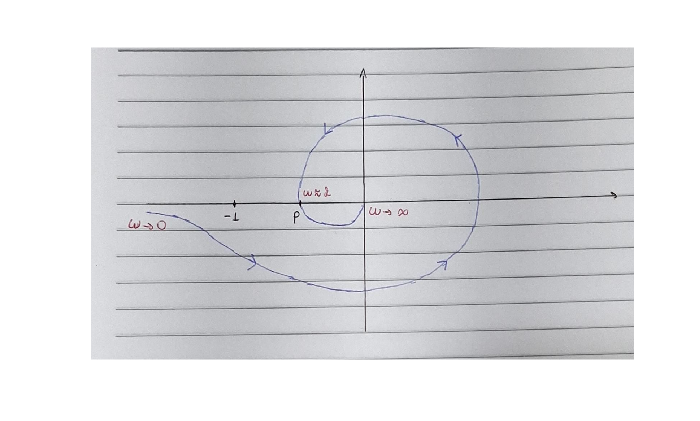

figure;
imshow('DiagramaNyquist_questao2.jpeg');

2.3 Verifique a estabilidade deste sistema em malha fechada, informando o número de polos de MF no SPD em caso de instabilidade.

**Como determinado nos itens anteriores, o sistema possui **$$N = 0$$** (não possui envolvimento em torno do ponto crítico no diagrama de Nyquist) e **$$P = 3$$** (três polos em malha aberta no Semiplano Direito). Pela equação do critério de Nyquist, temos:**


$$$$Z = N + P \to Z = 0 + 3 \to Z = 3$$$$


**Onde **$$Z$$** representa o número de polos da malha fechada (MF) localizados no Semiplano Direito (SPD). Como obtivemos **$$Z = 3
$$**, conclui-se que o sistema em malha fechada possui exatamente 3 polos no SPD, sendo, portanto, instável.**

## 3. Projeto de um controlador PD

O gráfico de Bode mostra o procedimento básico de projeto, que consiste em colocar o zero do PD, $s=-\frac{K_p}{K_d}$, próximo a wgl, onde a curva de módulo passa por 0dB.

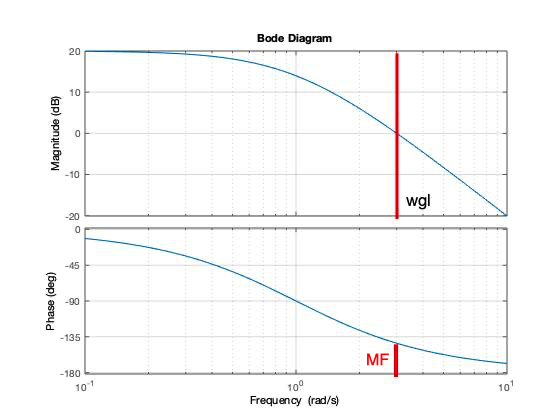

Use g1 fornecida para este projeto. 

Projete um controlador proporcional derivativo $C_1(s)=K_p +K_ds$ para atender as especificações: 

- Menor sobreelevação e tempo de estabelecimento possíveis

- Erro em regime $\leq 2\%$

Perguntas:

3.1) Qual o efeito do ganho calculado k para atender o erro em regime nas margens de ganho e de fase? Mostre no gráfico de Bode e explique.

**O cálculo do valor do ganho **$$K$$** deve levar em consideração as especificações de erro em regime, sobreelevação e tempo de estabelecimento. Como a função de transferência **$$G_1(s)$$** é do tipo 0 (pois não possui um integrador na origem), pode-se calcular a constante de erro de posição (**$$K_{ess}$$**) pela seguinte fórmula:**


$$$$e_{ss} = \frac{1}{1 + K_{ess}} \le 0,02 \to K_{ess} \ge 49$$$$


**Esse intervalo representa os valores que atendem exclusivamente ao critério de erro em regime. Para encontrar o ganho **$$K$$** correspondente, avaliamos o sistema para **$$\omega \to 0$$**, o que implica em **$$s \to 0$$**. Logo:**


$$$$G_1(0) = \frac{K}{40} \ge 49 \to K \ge 1960$$$$


**Analisando apenas a especificação do erro em regime, determinamos que **$$K \ge 1960$$**. Contudo, a adoção do valor de **$$K = 1960$$** desloca toda a curva de magnitude no diagrama de Bode, conforme a relação:**


$$$$20\log_{10}(K) = 20\log_{10}(1960) \approx 65,8 \text{ dB}$$$$


**Isso significa que a curva de magnitude é deslocada para cima em 65,8 dB. A fase, por sua vez, não sofre nenhuma alteração direta, pois o ganho adicionado é um número real e positivo.**

**Entretanto, ao elevar a curva de magnitude, a frequência de cruzamento de ganho (**$$\omega_{cg}$$**, o ponto onde a curva corta o eixo de 0 dB) é deslocada significativamente para a direita, alcançando frequências mais altas. Como a curva de fase deste sistema de 3ª ordem decai monotonicamente de **$$0^\circ$ até $-270^\circ$$**, cruzar o eixo de 0 dB em uma frequência muito maior significa que a fase nesse novo **$$\omega_{cg}$$** será muito mais negativa.**

**Conclui-se, portanto, que a Margem de Fase (MF) e a Margem de Ganho (MG) diminuem consideravelmente com a aplicação apenas deste ganho proporcional.**

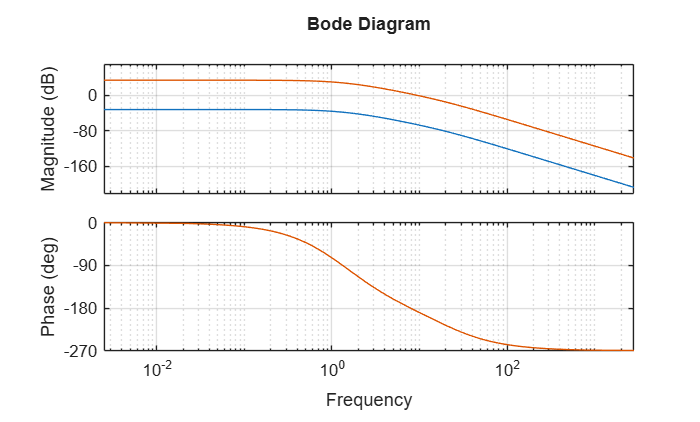

k=1960;  % Obter o ganho k para erro em regime especificado
figure
bode(g1,k*g1);grid;

**Pelo diagrama de Bode, ao observarmos a curva azul (sistema original com **$$K=1$$**), nota-se que na frequência onde a fase atinge -180° (aproximadamente 8 rad/s, ponto crítico para a estabilidade), a magnitude encontra-se significativamente abaixo de 0 dB. Isso significa que, no momento em que o sinal sofre a inversão de fase, o sistema atua atenuando esse sinal, o que impede a retroalimentação de crescer e garante que o sistema em malha fechada seja estável.**

**Por outro lado, ao aplicarmos o ganho **$$K=1960$$** (curva laranja), a curva de magnitude sofre um deslocamento vertical para cima, alterando a dinâmica do sistema. Ao analisarmos o comportamento nessa mesma frequência de -180°, constata-se que a magnitude agora ultrapassa a marca de 0 dB. Como o sistema passa a amplificar o sinal exatamente na frequência em que ele se inverte, cria-se uma realimentação positiva sustentada, o que leva o sistema à instabilidade.**

3.2) Projete um controlador PD c1 colocando o zero na frequência de cruzamento de ganho wgl (onde o módulo passar por 0dB) do item 3.1), explicitando a obtenção de  wgl.

**Podemos encontrar a frequência crítica através do denominador da função de transferencia. Pois, quando a fase é -180° significa que a parte imaginaria é igual a zero, portanto:**


$$$$D(s) = s^3 + 23s^2 + 62s + 40$$$$


**Substituindo **$$s = j\omega$$** e separando as partes real e imaginária, tem-se:**


$$$$D(j\omega) = (j\omega)^3 + 23(j\omega)^2 + 62(j\omega) + 40$$$$



$$$$D(j\omega) = -j\omega^3 - 23\omega^2 + j62\omega + 40$$$$



$$$$D(j\omega) = (40 - 23\omega^2) + j\omega(62 - \omega^2)$$$$



$$$$\omega(62 - \omega^2) = 0 \to \omega^2 = 62 \to \omega_{gl} \approx 7,87 \text{ rad/s}$$$$


wgl= 7.87 % Obter wgl do gráfico de Bode do item 3.1

wgl = 7.8700

c1 = projpd(g1, k, wgl)


c1 =
 
  249 s + 1960
 
Continuous-time transfer function.


3.2.1 Qual foi a margem de fase obtida? Plote o gráfico de Bode sem e com compensação e comente o efeito do zero nas curvas de fase e módulo e em que frequências.

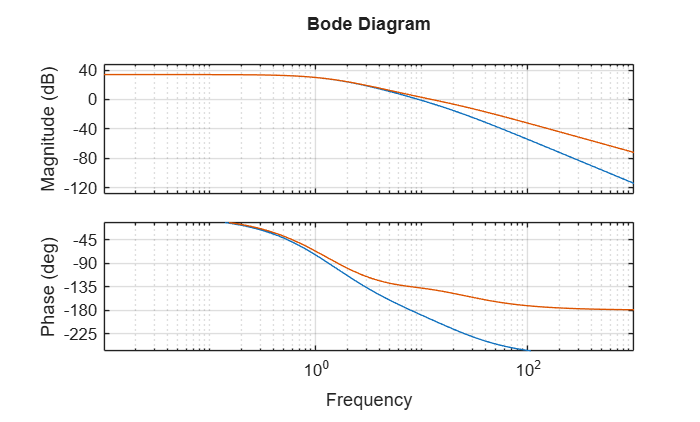

figure
bode(k*g1,c1*g1);grid;

**A Margem de Fase (MF) é identificada na frequência de cruzamento de ganho (**$$\omega_{cg}$$**), que é o ponto onde a curva de magnitude compensada (curva laranja) cruza o eixo de 0 dB. Observando o diagrama, esse cruzamento ocorre em aproximadamente **$$\omega \approx 10 \text{ rad/s}$$**. Ao analisarmos o diagrama de fase nessa mesma frequência, nota-se que a fase está em torno de **$$-135^\circ$$**. Dessa forma, a Margem de Fase obtida é:**


$$$$MF = 180^\circ + (-135^\circ) = 45^\circ$$$$


**A introdução do zero pelo controlador PD (alocado em **$$\omega = 7,87 \text{ rad/s}$$**) altera as curvas de frequência. No diagrama de fase, o zero insere um avanço gradual que atinge **$$+90^\circ$$** em altas frequências. Isso modifica o comportamento natural da planta original (que caía até **$$-270^\circ$$**), criando uma nova assíntota estabilizada em **$$-180^\circ$$**. Esse avanço é o responsável direto pelo aumento da Margem de Fase, o que garante a estabilidade do sistema e atua diminuindo a sobreelevação (overshoot) da resposta transitória.**

**No gráfico de módulo, o efeito do zero é um aumento na inclinação da curva em **$$+20 \text{ dB/déc}$$** a partir da sua frequência de atuação. Além disso, como o ponto crítico de instabilidade requer que o sistema cruze o eixo de **$$-180^\circ$$** e a nova fase do sistema compensado apenas se aproxima de **$$-180^\circ$$** como uma assíntota (sem nunca cruzá-la efetivamente para baixo), o sistema deixa de ter uma frequência de cruzamento de fase definida. Consequentemente, a Margem de Ganho teórica torna-se infinita.**

3.2.2 Simule o sistema com este controlador e comente os valores de UP, ts e erro em regime obtidos.

m1=feedback(c1*g1,1);
figure;
step(m1);
stepinfo_sr(m1);

     UP        tr         ts   
    ____    ________    _______

    34.8    0.092636    0.62299



**A simulação do sistema em malha fechada com o controlador PD projetado demonstrou que o critério de erro em regime permanente atendeu à especificação inicial do projeto (**$$e_{ss} \le 2\%$$**). Isso pode ser constatado pela resposta ao degrau unitário, que estabilizou em uma amplitude de aproximadamente 0,98, resultando em um erro de 2%. Em relação à resposta transitória, o sistema apresentou uma sobreelevação considerável de 34,8%. Esse aumento no sobressinal é uma consequência direta do *****trade-off***** do projeto no domínio da frequência: a inserção do zero do controlador PD na malha direta é para fornecer o avanço de fase que garante a estabilidade, mas tende a amplificar a amplitude do primeiro pico. Por outro lado, o tempo de estabelecimento (**$$t_s$$**) obtido foi bastante rápido, atingindo 0,623 segundos.**

3.3) Varie a localização do zero do PD antes e depois de wgl, usando os 9 valores gerados abaixo. Plote MF, UP e ts em função de wgl escolhida.

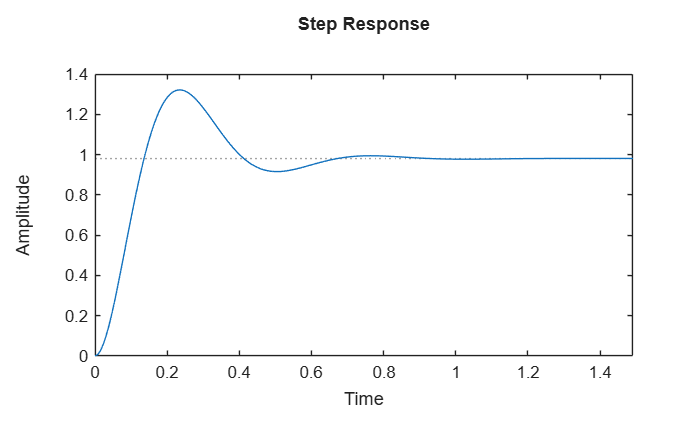

P=[];
f=wgl*(0.3:0.2:2); % Valores sugeridos. Mude se não ficar bom
for i=1:length(f)
    [ c, mf ] =projpd( g1, k, f(i) );
    m=feedback(c*g1,1);
    S=stepinfo(m);
    P=[P;[mf S.Overshoot S.SettlingTime]];
end
tit={'MF(graus)','UP(%)','ts(s)'};

for i=1:3
    subplot(3,1,i);bar(f,P(:,i));title(tit{i});
end

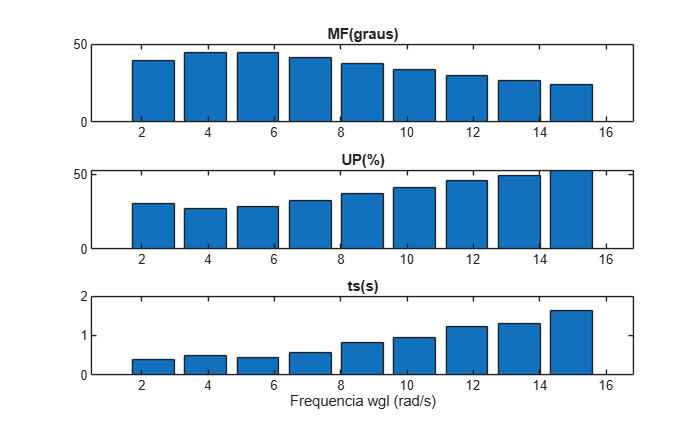

xlabel('Frequencia wgl (rad/s)')

3.3.1 Qual foi o efeito do aumento da MF em UP? Use valores do gráfico para explicar.

**O aumento da Margem de Fase (MF) ocasiona uma redução direta na sobreelevação (UP). Isso ocorre porque a MF é diretamente proporcional ao coeficiente de amortecimento do sistema. Logo, aumentar a MF significa injetar mais amortecimento na malha, o que atua freando a resposta transitória e reduzindo o pico de overshoot.**

**Esse comportamento teórico é comprovado pelos dados do gráfico: quando o zero é alocado próximo a wgl = 4 rad/s, o sistema atinge sua maior Margem de Fase (aproximadamente 48°), o que resulta na menor sobreelevação registrada (cerca de 28%). Em contrapartida, ao deslocar o zero para frequências mais altas, como em wgl = 14 rad/s, a MF é reduzida quase pela metade (aproximadamente 25°), causando uma queda no amortecimento que faz a sobreelevação aumentar para cerca de 50%.**

3.3.2 Qual foi o efeito do aumento da MF em ts? Use valores do gráfico para explicar.

**O aumento da Margem de Fase (MF) resulta na redução do tempo de estabelecimento (ts). Como a MF é diretamente proporcional ao coeficiente de amortecimento do sistema, um aumento na MF injeta mais amortecimento na malha. Isso faz com que o sistema oscile menos e, consequentemente, atinja a faixa de regime permanente mais rapidamente (menor ts).**

**Esse comportamento fica evidente ao compararmos os extremos do gráfico: quando o zero é alocado próximo a wgl = 4 rad/s, o sistema atinge sua maior MF (aproximadamente 48°), o que resulta em um tempo de estabelecimento pequeno (ts em torno de 0,5 segundos). Em contrapartida, quando o zero é alocado em wgl = 15 rad/s, a MF cai para o seu menor valor (cerca de 25°); com a perda de amortecimento, o sistema oscila mais (sobreelevação de 50%) e demora muito mais para estabilizar, resultando no maior ts (aproximadamente 1,7 segundos).**

3.3.3 Usando os gráficos do item 3.3, escolha o valor  wgl1 onde colocar o zero do PD para obter a menor sobreelevação e tempo de estabelecimento possíveis e mostre o resultado obtido com esta escolha.

wgl1=5 % Obter do item 3.3

wgl1 = 5

c1 =projpd( g1, k, wgl1)


c1 =
 
  392 s + 1960
 
Continuous-time transfer function.


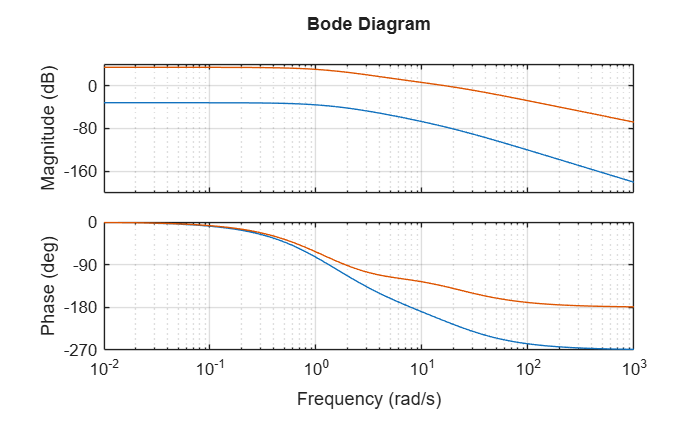


m1=feedback(c1*g1,1);
figure;
bode(g1,c1*g1);grid;

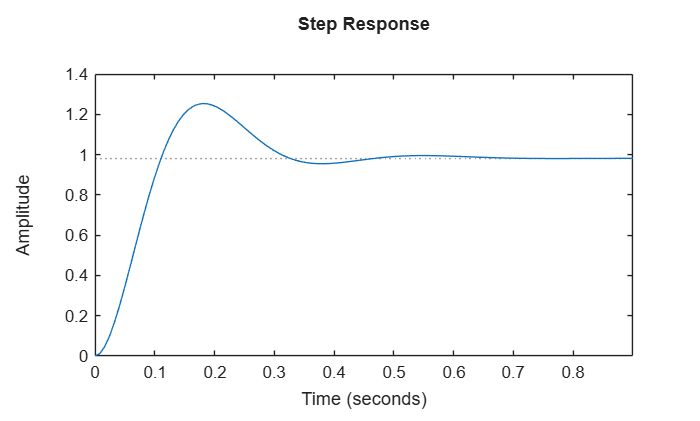

figure;
step(m1);

stepinfo_sr(m1);

     UP        tr         ts   
    ____    ________    _______

    27.9    0.075023    0.41189



Comentar o resultado:

**A partir da análise dos gráficos obtidos no item 3.3, optou-se por posicionar o zero do controlador PD em wgl1 = 5 rad/s. Essa escolha fundamenta-se na busca pelo melhor compromisso (*****trade-off*****) para atender simultaneamente às especificações do projeto. Embora frequências menores, como wgl = 2 rad/s, apresentem um tempo de estabelecimento (ts) ligeiramente inferior, elas resultam em uma sobreelevação (UP) mais acentuada. Portanto, a alocação em 5 rad/s foi escolhida por garantir a menor sobreelevação possível dentre as opções viáveis, sacrificando apenas uma fração mínima no tempo de estabelecimento e resultando no comportamento geral mais equilibrado para o sistema.**

## 4. Projeto de um controlador PI

Use g2 fornecida para este projeto. 

Lembramos que o projeto do PI para aumentar a margem de fase é feito abaixando a curva de módulo de g2.

Projete um controlador proporcional integral $C_2(s)=K_p +K_i/s$ para atender as especificações: 

- Sobreelevação $\leq20\%$

- Menor tempo de estabelecimento possível

4.1 Faça o projeto do controlador PI  sem alterar a curva de módulo, de modo a apenas garantir o erro nulo para entrada degrau em regime.

      Plote o gráfico de Bode de g2 e de c2g2 bem como a resposta ao degrau e responda as seguintes perguntas. 

c2=projpi(g2,0)


c2 =
 
  s + 4.605
  ---------
      s
 
Continuous-time transfer function.


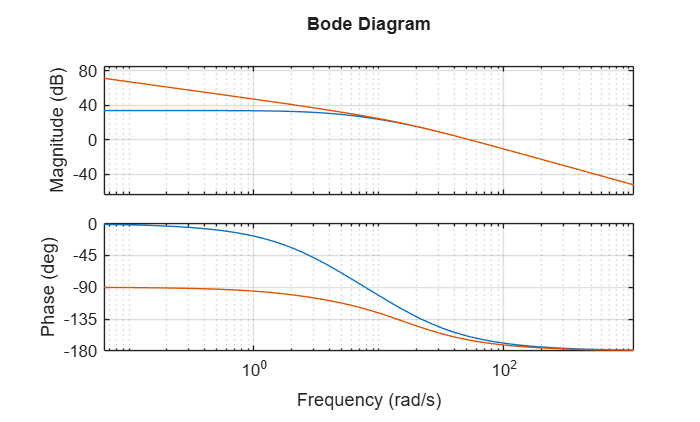


figure;
bode(g2,c2*g2);grid;

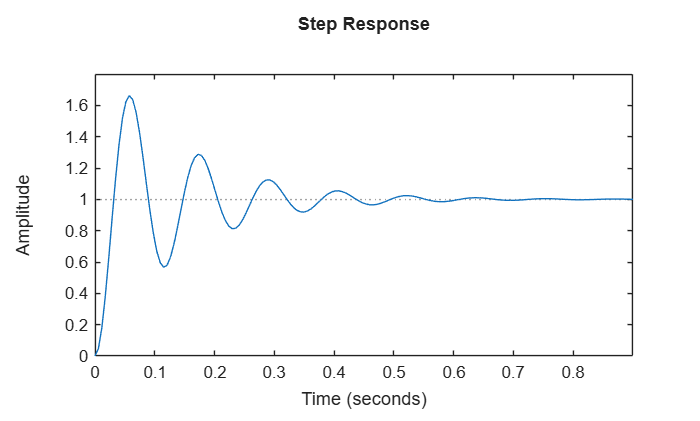

figure;
m2=feedback(c2*g2,1);
step(m2);

stepinfo_sr(m2);

     UP        tr         ts   
    ____    ________    _______

    66.2    0.021116    0.53173



4.1.1 Qual o valor de wgl  e qual a margem de fase obtidas? 

**O valor da frequência de cruzamento de ganho (**$$\omega_{cg}$$** ou wgl) é identificado no diagrama de Bode pelo ponto em que a curva de magnitude do sistema compensado (curva laranja) cruza o eixo de **$$0 \text{ dB}$$**. Observando o gráfico, esse cruzamento ocorre exatamente em **$$\omega_{cg} = 50 \text{ rad/s}$$**.**

**Ao analisarmos o diagrama de fase para a curva laranja nessa mesma frequência de 50 rad/s, nota-se que a fase encontra-se próxima à linha crítica. Assumindo um valor aproximado de fase em torno de **$$-150^\circ$$**, a Margem de Fase pode ser calculada como:**


$$$$MF = 180^\circ + (-150^\circ) \approx 30^\circ$$$$


**Portanto, a Margem de Fase obtida é aproximadamente 30°**

4.1.2 Em que frequência está o zero do PI?

**A partir da função de transferência do controlador PI gerada pelo projeto (**$$C_2(s) = \frac{s + 4,605}{s}$$**), a localização do zero é determinada igualando o polinômio do numerador a zero. Portanto, resolvendo **$$s + 4,605 = 0$,$** conclui-se que o zero do controlador PI está localizado na frequência de **$$\omega = 4,605 \text{ rad/s}$$**. Essa localização em baixa frequência (significativamente abaixo da frequência de cruzamento de ganho **$$\omega_{cg} = 50\text{ rad/s}$$**) é característica do projeto do PI para tentar mitigar o atraso de fase gerado pelo polo na origem antes do ponto crítico de estabilidade.**

4.2 Avalie o projeto do PI para 10 valores de redução de módulo m, plotando um gráfico de barras de MF, UP, ts em função do módulo reduzido.

Para isso, obtenha m0, o valor de módulo que deve ser reduzido para se ter MF=90graus. Os valores a serem testados estarão entre 0 e m0, dados por  m=-linspace(0,m0,10);

A avaliação dos valores de m, todos menores ou iguais a zero, é feita com o comando [ C, wg, mf, UP, ts ] =projpi( g, m); que segue os passos de projeto.

m0=20 % Obter do grafico de Bode de g2

m0 = 20

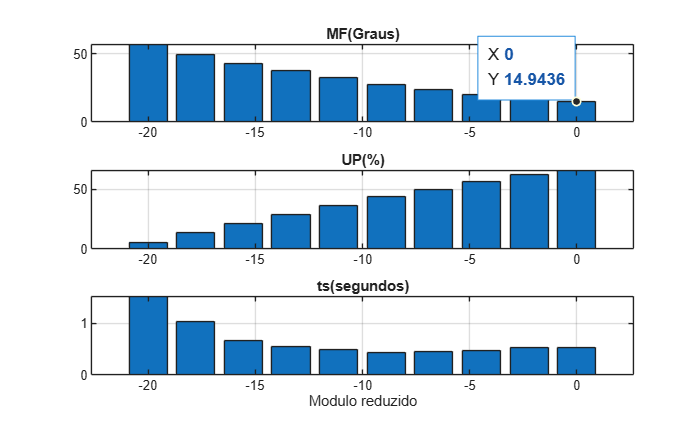

m=-linspace(0,m0,10);
[ C, wg, mf, UP, ts ] =projpi(g2, m);
figure;
subplot(311);bar(m,mf);grid;title('MF(Graus)');
subplot(312);bar(m,UP);grid;title('UP(%)');
subplot(313);bar(m,ts);grid;title('ts(segundos)');xlabel('Modulo reduzido');

4.2.1 Qual o efeito da redução do módulo em MF? Que valores foram obtidos?

**A redução do módulo causa um aumento na Margem de Fase (MF). Isso ocorre porque rebaixar a curva de magnitude desloca a frequência de cruzamento de ganho para valores menores, onde o atraso de fase do sistema é menos severo.**

**Analisando os valores obtidos no gráfico, nota-se que quando não há redução de módulo (0 dB), a MF é a menor possível (aproximadamente 15°), o que resulta em um sistema pouco amortecido com sobreelevação (UP) altíssima (acima de 60%). Em contrapartida, ao aplicarmos a redução máxima testada (-20 dB), a MF aumenta significativamente e atinge seu valor máximo (aproximadamente 55°), o que injeta amortecimento na malha e derruba a sobreelevação para perto de 5%.**

4.2.2 Qual o efeito da redução do módulo em UP?Qual o valor de redução de módulo para o qual UP<20%?

**A redução do módulo provoca uma diminuição direta na sobreelevação (UP). Isso acontece porque a atenuação da curva de magnitude desloca a frequência de cruzamento para uma região mais segura, aumentando a Margem de Fase. Esse aumento reflete-se em um maior coeficiente de amortecimento, o que atua 'freando' a resposta transitória e reduzindo a oscilação do sistema.**

**Analisando o gráfico de barras, nota-se que uma redução de 18 dB  resulta em uma sobreelevação de aproximadamente menor que 20%. Com base nessa aproximação, a especificação exigida (UP **$$\le$$** 20%) é atendida.**

4.2.3 Qual o efeito da redução do módulo em ts?Qual o menor valor de ts para o qual tem-se UP<20%?

**A redução do módulo provoca um aumento no tempo de estabelecimento (**$$t_s$$**). Isso ocorre porque o rebaixamento da curva diminui a frequência de cruzamento de ganho, reduzindo a largura de banda do sistema. Um sistema com menor largura de banda é fisicamente mais lento, demorando mais tempo para atingir e estabilizar na referência.**

**Para determinar o menor valor de **$$t_s$$** viável, deve-se primeiro respeitar a restrição de sobreelevação (UP **$$\le$$** 20%). Analisando os gráficos, a menor redução de módulo capaz de satisfazer esse critério de amortecimento ocorre em aproximadamente -18 dB. Nesse ponto de operação, o tempo de estabelecimento correspondente, e o menor possível dentro da especificação, é de aproximadamente 1,0 segundos.**

4.3 Baseado nos gráficos feitos em 4.2, escolha o valor de módulo mi a ser reduzido que atenda as especificações e plote a resposta ao degrau e o gráfico de Bode de de g2 e de c2g2, verificando o atendimento das especificações.

mi=-18 % Obter dos gráficos do Item 3.2

mi = -18

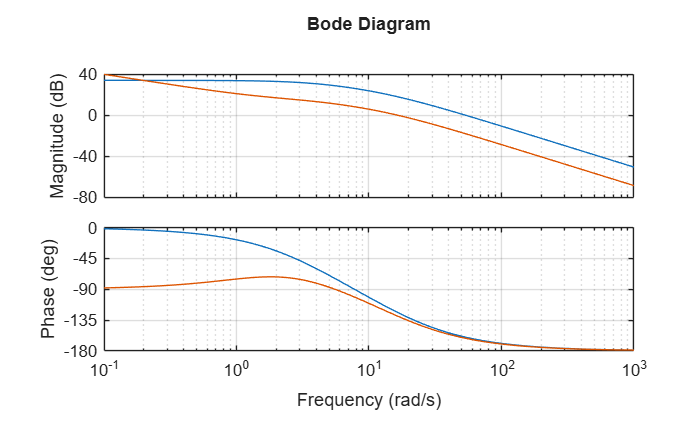

c2 =projpi(g2 , mi);
figure;
bode(g2,c2*g2);grid;

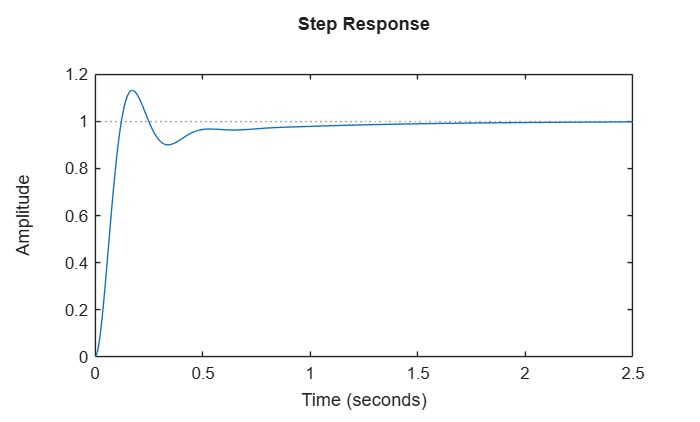

m2=feedback(c2*g2,1);

figure;step(m2);

stepinfo_sr(m2);

     UP        tr         ts  
    ____    ________    ______

    13.1    0.082549    1.0574



**Baseado na análise realizada no item 4.2, o valor de módulo escolhido para a redução foi **$$m_i \approx -18 \text{ dB}$$**. Como pode ser verificado nos gráficos de Bode e na resposta ao degrau plotados a seguir, essa escolha atende às especificações do projeto: o sistema estabiliza com erro nulo em regime, a sobreelevação (UP) foi contida para um valor inferior a 20%, e o tempo de estabelecimento (**$$t_s$$**) manteve-se no menor patamar possível (cerca de 1,0 segundo) para essa restrição de amortecimento.**

4.4 A partir do controlador PI do item 4.3, projete um PID c23=c2*c3 adicionando o zero do PD próximo a wgl2, explicando a escolha e mostrando a FT do PID.

wgl2=5; % Selecionar valor do gráfico de Bode do item 3.3
c3=tf([1/wgl2 1],1);
c23=c2*c3


c23 =
 
  0.02518 s^2 + 0.1651 s + 0.1959
  -------------------------------
                 s
 
Continuous-time transfer function.


**Para a composição do controlador PID final (**$$C_{23}(s)$$**), a localização do zero da parcela derivativa (PD) foi definida em **$$\omega_{gl2} = 5 \text{ rad/s}$$**. Essa escolha baseia-se diretamente na análise realizada no item 3.3. Naquela etapa, comprovou-se que alocar o zero nessa frequência específica oferece o melhor compromisso para a malha de avanço de fase, garantindo a redução efetiva da sobreelevação sem penalizar excessivamente o tempo de estabelecimento do sistema.**

**A Função de Transferência (FT) resultante da multiplicação da parcela PI (**$$C_2$$**) pela parcela PD (**$$C_3$$**) é dada por:**

`c23 =`

`  0.02518 s^2 + 0.1651 s + 0.1959`

`  -------------------------------`

`                 s`

4.4.1 Plote a resposta ao degrau e o gráfico de Bode de g2 e de g2 com o PI e o PID,  verificando o atendimento das especificações 

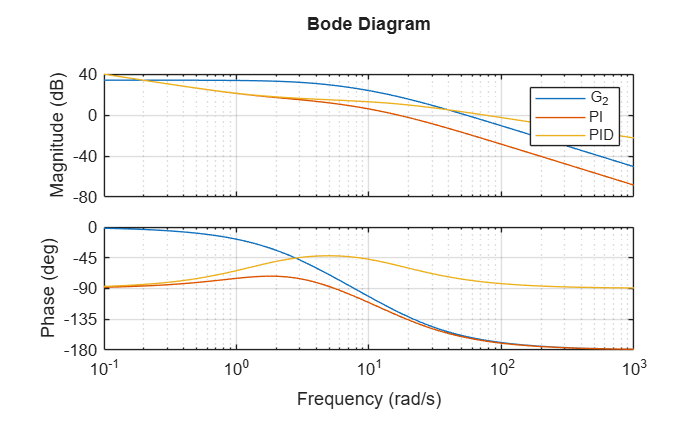

figure;
bode(g2,c2*g2,c23*g2);grid;legend('G_2','PI','PID');

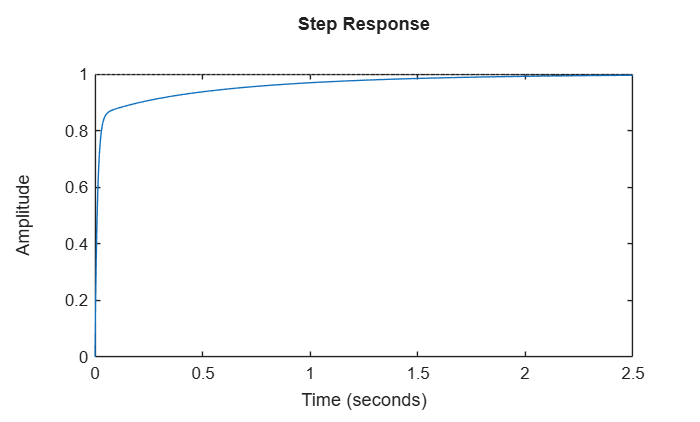

M1=feedback(c23*g2,1);
figure;step(M1);

stepinfo_sr(M1);

    UP      tr         ts  
    __    _______    ______

    0     0.20677    1.2971



Comentários:

**Analisando o Diagrama de Bode do sistema compensado com PID (curva amarela), observa-se que a adição do zero da ação derivativa alterou o comportamento em altas frequências. No gráfico de fase, esse zero extra fornece um avanço que cria uma assíntota em **$$-90^\circ$$**. Como a curva de fase nunca atinge o ponto crítico de **$$-180^\circ$$**, o sistema possui uma Margem de Ganho infinita, garantindo robustez contra instabilidade. Além disso, a Margem de Fase resultante é bastante elevada (aproximadamente **$$90^\circ$$**).**

**No domínio do tempo, a resposta ao degrau comprova que as especificações do projeto foram atendidas. A elevada Margem de Fase eliminou completamente as oscilações, resultando em uma sobreelevação nula (UP = 0%), o que atende com folga a restrição de **$$\le 20\%$$**. O tempo de estabelecimento (**$$t_s$$**) foi de 1,29 segundos; esse leve aumento em relação ao projeto puramente PI (**$$\approx 1,0 \text{ s}$$**) é um compromisso (*****trade-off*****) aceitável e não significativo, dado o benefício da eliminação total do *****overshoot*****.**

Esta função calcula e mostra UP, tr, ts

function stepinfo_sr(g)
S=stepinfo(g);
UP=S.Overshoot;
UP=floor(UP*10)/10;
ts=S.SettlingTime;
tr=S.RiseTime;
T=table(UP,tr,ts);
disp(T);
end